clear;clc;

% This code confirms the Communications Toolbox Library for ZigBee
% and UWB add-on is installed.
% commSupportPackageCheck('ZIGBEE');

msg = randi([0 1], 1000, 1);
cfgHPRF = lrwpanHRPConfig(Channel=6,Mode='HPRF', PSDULength=length(msg)/8) %#ok<NOPTS>

cfgHPRF =   lrwpanHRPConfig - 属性:

                   Channel: 6
                      Mode: 'HPRF'
                   MeanPRF: 249.6000
           SamplesPerPulse: 4
                 CodeIndex: 25
          PreambleDuration: 64
                 SFDNumber: 0
                   Ranging: 0
          ConstraintLength: 3
                PSDULength: 125

   STS:
    STSPacketConfiguration: 1
            NumSTSSegments: 1
          STSSegmentLength: 64

   Read-only properties:
                SampleRate: 1.9968e+09


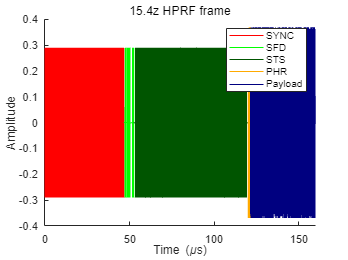

waveHPRF = lrwpanWaveformGenerator(msg, cfgHPRF);
lrwpanPlotFrame(waveHPRF, cfgHPRF);


% Cache preamble, to use in preamble detection. 
% Get the 1st instance out of the Nsync=PreambleDuration repetitions.
indices = lrwpanHRPFieldIndices(cfgHPRF); % length (start/end) of each field
preamble = waveHPRF( ...
    1:indices.SYNC(end)/cfgHPRF.PreambleDuration); % 1 of the Nsync repetitions






% % 计算持续时间
% Fs = cfgHPRF.SampleRate; % 采样率
% numSamples = length(waveHPRF); % 样本数
% duration = numSamples / Fs; % 持续时间
% 
% % 绘制HRP信号时域波形
% t = (0:numSamples-1) / Fs;
% figure;
% plot(t, waveHPRF);
% xlabel('time(second)');
% ylabel('Amplitude');
% title('the waveform of HRP signals in time domain');


environmentType = "Residential";
LOS             = true;
channelSpec = [6 6988.8e6 499.2e6];
channelNum = channelSpec(1);
Fc = channelSpec(2);
bw = channelSpec(3);
fprintf('Channel #%d: Center frequency = %.1f MHz, Bandwidth = %.1f MHz.\n', channelNum, Fc/1e6, bw/1e6);

Channel #6: Center frequency = 6988.8 MHz, Bandwidth = 499.2 MHz.


d = 10; % distance between transmitter and receiver, in meters
sampleDensity   = 10000;
maxDopplerShift = 5; % in Hz

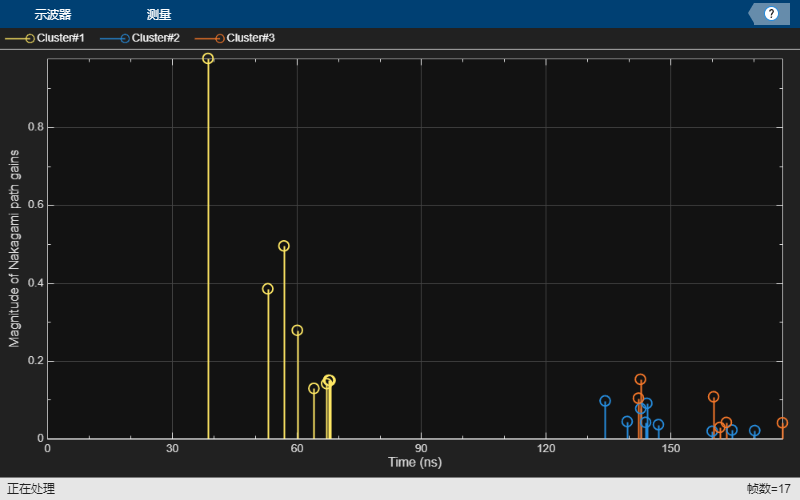

uwbChan = uwbChannel(environmentType, LOS, ChannelNumber=channelNum, Distance=d, ...
  SampleRate=cfgHPRF.SampleRate, SampleDensity=sampleDensity, MaxDopplerShift=maxDopplerShift, ...
  Visualization="Impulse response");
rcvSig = uwbChan(waveHPRF); % filter UWB waveform

s = info(uwbChan)   % display info about the UWB channel

s = 包含以下字段的 struct :
    EnvironmentParameterization: [1×1 struct]
                CenterFrequency: 6.9888e+09
                      Bandwidth: 499200000
                    NumClusters: 3
            ClusterArrivalTimes: [38.6968 134.2866 142.2903]
                ClusterEnergies: [0.0809 0.0011 0.0034]
               PathArrivalTimes: {[0 14.3934 18.2709 21.4891 25.4905 28.5521 29.0468 29.3657]  [0 5.2913 8.5575 9.7166 10.0204 12.8091 25.7589 30.5006 35.9848]  [0 0.4744 18.0880 19.5596 21.1611 34.6446]}
       AbsolutePathArrivalTimes: {[38.6968 53.0902 56.9677 60.1859 64.1873 67.2489 67.7436 68.0625]  [134.2866 139.5779 142.8440 144.0032 144.3070 147.0957 160.0455 164.7872 170.2714]  [142.2903 142.7647 160.3783 161.8499 163.4513 176.9349]}
              PathAveragePowers: {[0.4315 0.1368 0.1004 0.0777 0.0564 0.0442 0.0425 0.0414]  [0.0057 0.0038 0.0029 0.0026 0.0026 0.0021 7.3247e-04 5.0170e-04 3.2386e-04]  [0.0180 0.0174 0.0043 0.0038 0.0033 0.0011]}
                     PathPhases

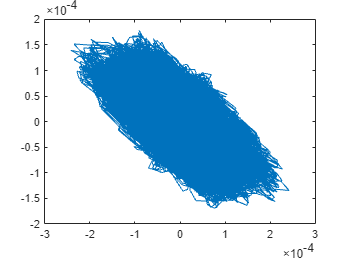

% 绘制接收信号的时域波形图
t = (0:length(rcvSig)-1) / cfgHPRF.SampleRate; % 时间向量，单位为秒
% 计算接收信号的归一化幅度
rcvSig_normalized = abs(rcvSig) / max(abs(rcvSig));
% 绘制归一化幅度图
figure;
plot(rcvSig)

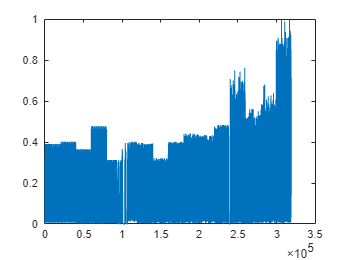

plot(rcvSig_normalized); % 绘制归一化幅度图

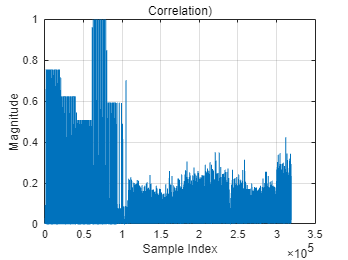

% xlabel('time(second)');
% ylabel('normalization');
% title('receive signal after normalization');

% Calculate CIR (example using the correlation matrix)
cir = abs(filter(flipud(preamble),1,rcvSig)); % Example: Using cross-correlation
% cir = cir(length(preamble):end); % Discard unnecessary part
cir = cir / max(cir); % Normalize

% Plot CIR
figure;
plot(cir);
xlabel('Sample Index');
ylabel('Magnitude');
title('Correlation)');
grid on;


% 计算两点之间的欧氏距离
function distance = calculate_distance(point1, point2)
    % point1 和 point2 分别是两个点的坐标，格式为 [x, y]
    distance = norm(point1 - point2);
end

% 发射端和接收端的位置坐标
lambda=0.095;
% nTx=3;
% nRx=1;
transmitter_position_1 = [10+lambda/2, 5];
transmitter_position_2 = [10+lambda, 5];
transmitter_position_3 = [10+3*lambda/2, 5];
receiver_position = [0, 0];
distance1=calculate_distance(transmitter_position_1,receiver_position);
distance2=calculate_distance(transmitter_position_2,receiver_position);
distance3=calculate_distance(transmitter_position_3,receiver_position);


%Draw the simulation scenarios
function ShowLocations(deviceLoc, nodeLoc)
%HELPERSHOWLOCATIONS Visualize device and node positions in a 2D plane

%   Copyright 2021 The MathWorks, Inc. 

f = figure;
ax = gca(f);

% Device
plot(ax, deviceLoc(1), deviceLoc(2), 'mp');

hold(ax, 'on')

% Nodes
plot(ax, nodeLoc(:, 1), nodeLoc(:, 2), 'kd');
text(ax, nodeLoc(1, 1)+1.5, nodeLoc(1, 2)-1, 'A');
text(ax, nodeLoc(2, 1)+1.5, nodeLoc(2, 2)-1, 'B');
text(ax, nodeLoc(3, 1)+1.5, nodeLoc(3, 2)-1, 'C');

axis(ax, [0 100 0 100])

legend('anchor', 'device', 'Location', 'NorthWest')
end

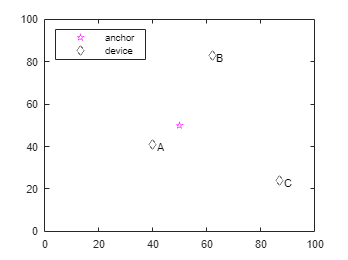

%Configuration
numNodes = 3;
anchorLoc = [50 50];  % place device at the center
tagLoc = [40 41;
           62 83;
           87 24];
ShowLocations(anchorLoc,tagLoc)

% Calculate antenna positions for each tag
lambda =physconst("LightSpeed")/(3.5e9); % wavelength (assume)
antennaSpacing = lambda / 2;
numAntennas = 3;
antennaLoc=[40 41;40+antennaSpacing 41;40+2*antennaSpacing 41]

antennaLoc =    40.0000   41.0000
   40.0428   41.0000
   40.0857   41.0000


actualDistances = sqrt(sum((anchorLoc-antennaLoc).^2, 2));
actualTOF = actualDistances/c;

函数或变量 'c' 无法识别。

firstPreamblePhase=NaN(1,numAntennas);
vfd = dsp.VariableFractionalDelay;
for idx=1:numAntennas
    tof=actualTOF(idx)
    samplesToDelay = tof * blinkPHYConfig.SampleRate;
    reset(vfd);
    release(vfd);
    vfd.MaximumDelay = ceil(1.1*samplesToDelay);
    delayedBlink = vfd( ...
        [waveHPRF; zeros(ceil(samplesToDelay), 1)], ...
        samplesToDelay);
    % Add white Gaussian noise
    receivedBlink = awgn(delayedBlink,SNR);
    preamPos = helperFindFirstHRPPreamble( ...
        receivedBlink,preamble,cfgHPRF);
    firstPreamblePhase(idx)=receivedBlink(preamPos)
end